# Chemical Process Optimization Overview

This introductory sample demonstrates how to teach a policy for controlling a chemical process, specifically a CSTR, Continuous Stirred Tank Reactor. There are two tutorials included ion this sample. Tutorial 1 focuses on controlling concentration from 8.57 to 2 kmol/m3. Tutorial 2 focuses on conctrolling concentration under the same scenario, this time introducing gaussian noise in control and temperature read-outs.

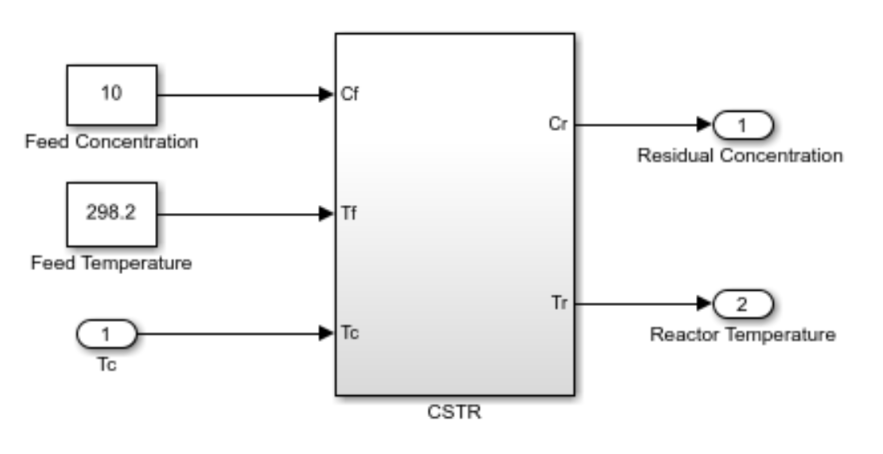

To learn more about this simulation, including benchmark control, check out: [Gain-Scheduled Control of a Chemical Reactor (MATLAB & Simulink)](https://www.mathworks.com/help/control/ug/gain-scheduled-control-of-a-chemical-reactor.html).

## Model Overview

# TODO: Journey

## Running Model

There are two ways to run the model. The first is to test the model using Benchmark Control. This allows you to run the model without the connection to Bonsai to get an understanding of how well a good control performs. 

## **Run Locally using Benchmark Control**

To run the benchmark control, first open the Simulink model:

ChemicalProcessOptimization;

Then, select the Variant Subsystem called GainScheduled (double-click the Variant Subsystem box to see pop-up menu):

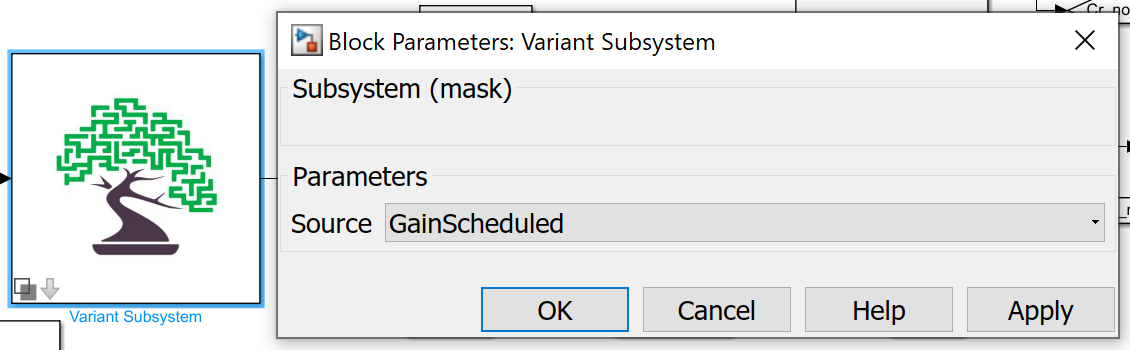

Now, after selecting GainScheduled and clicking OK, you can run the benchmark script:

Constant Gains: Target Concentration followed with RMS of: 1.4835
Constant Gains: Target Reactor Temperature followed with RMS of: 18.1427
~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


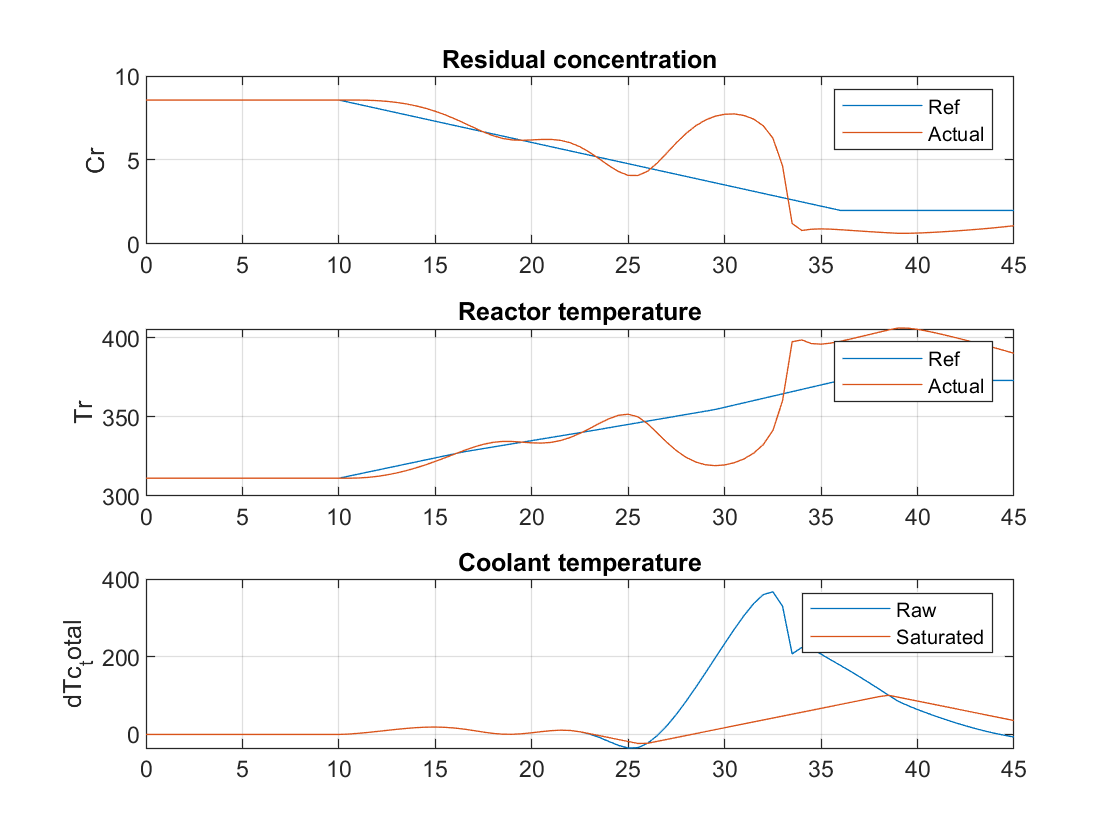

Benchmark: Target Concentration followed with RMS of: 0.56409
Benchmark: Target Reactor Temperature followed with RMS of: 4.6046
~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


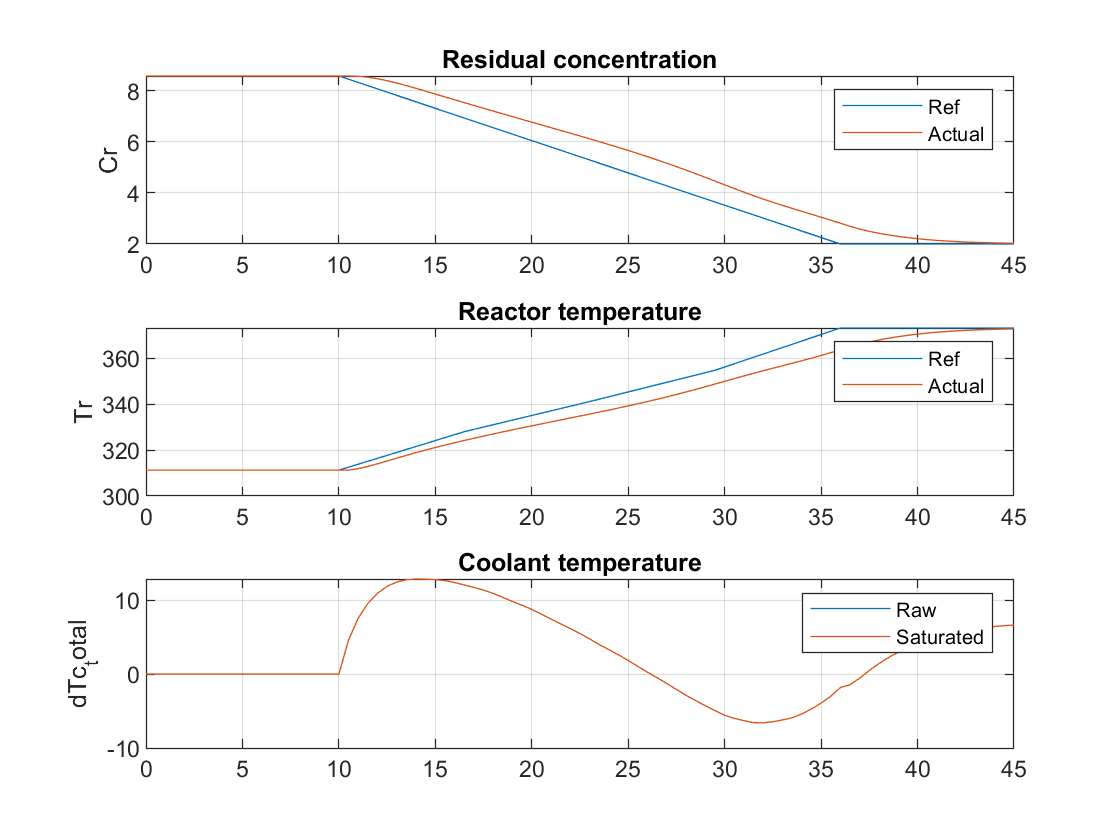

Strech Benchmark (5% noise): Target Concentration followed with RMS of: 3.337
Strech Benchmark (5% noise): Target Reactor Temperature followed with RMS of: 33.1682
~~~~~~~~~~~~~~~~~~~~~~~~~~~~~


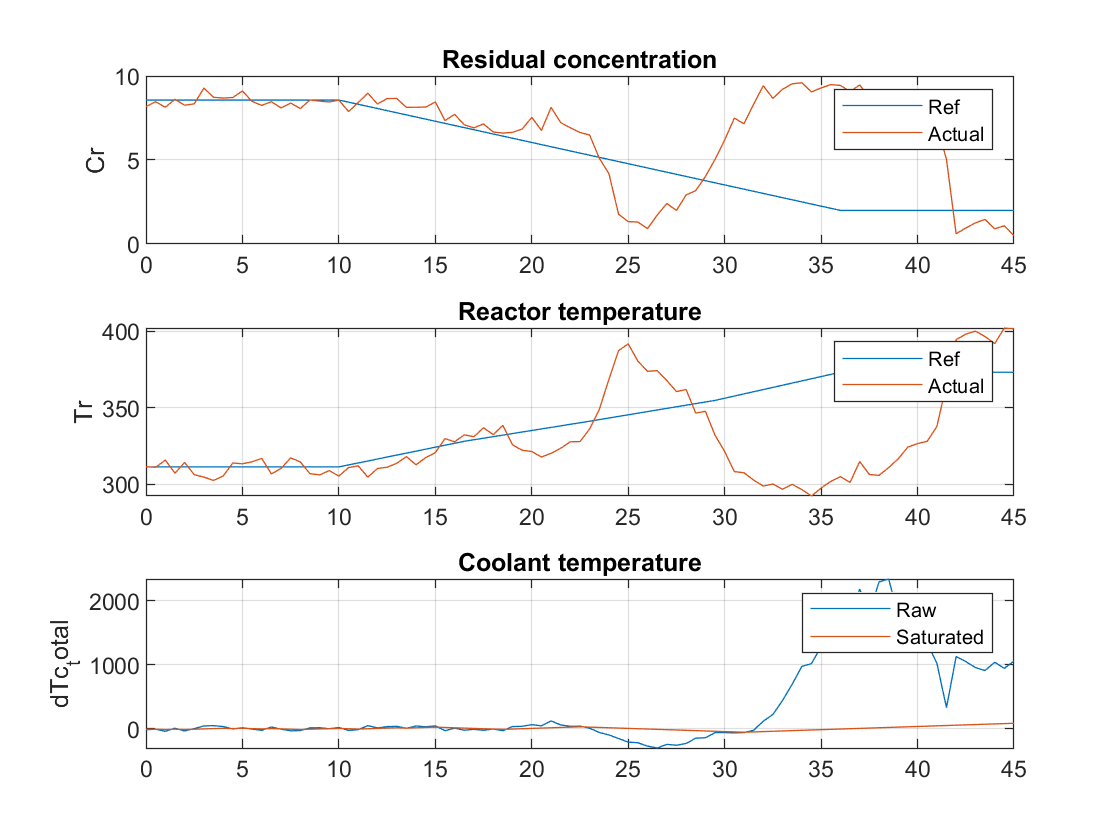

run_benchmark;

After entering this command, benchmark will be run under 3 scenarios (see more bellow). Graphs will be shown for each of them independently.

### Benchmark - 3 Scenarios

These are the three scenarios that are run for Benchmark Control:

- Constant Gains: This scenario runs without scheduled gains for the 2 bechmark controls. It allows the user to assess the simulation non-linearities that force benchmark to require 2 controls, with 5 non-linear gains.

- Scheduled Gains: This second scenario runs benchmark as engineered. It allows you to assess how well does the current system perform. New controllers (including Bonsai brains) will be compared against this scenario to assess over/under performance.

- Benchmark Stretched:This last scenario assesses how well does benchmark perform under the influence of gaussian noise on the temperature/concentration read-outs. In a real application, read-outs might be subject to noise, as well as measurement error. This scenario tests robustness to noise.

### Modifying Parameters

Each scenario is introduced in a separate section inside the run_benchmark.m script. There's 2 elements that you might be the most interested in changing:

- Equilibrium Concentration: Modifying the final concentration that the control will have to reach.

- Equilibrium Time: Modifying how quickly benchmark should hit the target concentration.

- Noise Magnitude: Modifying the amount of noise introduced to the model on Benchmark Stretched scenario.

(1) To modify the first two, both equilibrium concentration and time, go and find the following lines of code at the 2nd section of the 'run_benchmark.m' script:

open_system('ChemicalProcessOptimization')

% This writes to the Default Signal builder (Cref_signal = 1)
target_t = [0; 10; 36; 45];
target_Cr = [8.57; 8.57; 2; 2]; 
signalbuilder('ChemicalProcessOptimization/Target concentration', 'set', 'Signal 1', 'Group 1', target_t, target_Cr);

Then, modify them with the following:

open_system('ChemicalProcessOptimization')

% Equilibrium values (both time and concentration)
equilibrium_time = 36;
equilibrium_concentration = 5;

% This writes to the Default Signal builder (Cref_signal = 1)
target_t = [0; 10; equilibrium_time; 45];
target_Cr = [8.57; 8.57; equilibrium_concentration; equilibrium_concentration]; 
signalbuilder('ChemicalProcessOptimization/Target concentration', 'set', 'Signal 1', 'Group 1', target_t, target_Cr);

You are good to go:

- Make controller go faster setting a smaller value for equilibrium_time (threshold at 10)

- Make controller go slower setting a larger value for equilibrium_time (threshold at 45)

- Modify the equilibrium concentration to make it go lower or higher than 2 (value must be within 1 and 8.57)

(2) To modify the noise introduced during Benchmark Stretched, go and find the following line under "Benchmark (stretch - 5% noise)" section:

% Percentage of noise to include
noise_magnitude = 5/100;

Modify 5 to whichever value you desired within [0, 100] range.

### Important!

To make sure that you don't run into issues when training with Bonsai, make sure to always run the 2nd to last section of 'run_benchmark.m'. This will take care of correcting any changes performed to equilibrium time and concentration (Signal 1):

%% Initialize Default Variables to avoid issues with Bonsai training
% i.e. signal builder
% no noise, etc
init_vars

% This writes to the Default Signal builder (Cref_signal = 1)
target_t = [0; 10; 36; 45];
target_Cr = [8.57; 8.57; 2; 2]; 
signalbuilder('ChemicalProcessOptimization/Target concentration', 'set', 'Signal 1', 'Group 1', target_t, target_Cr);

## **Run Locally using Bonsai Controller**

After getting acclimated with the Chemical Process Optimization model and setting up a Bonsai account, you are now ready to train your first Bonsai brain for this simulation. Be sure to select **Bonsai** in the Controller block and save your model. 

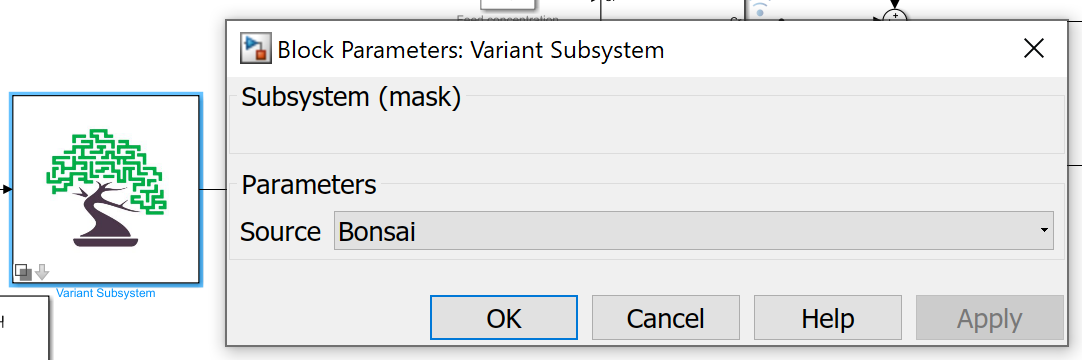

Be sure to **Save** and **Close** the model with the Bonsai Controller selected.

### Connect to Bonsai

If you have not done so, you will need to create a Bonsai [account](https://docs.microsoft.com/en-us/bonsai/quickstart/setup). 

From the Bonsai UI, you will need to capture your Bonsai **Workspace ID **and **Access Key**.

#### Create a Brain

In the Bonsai UI click `+Create Brain:`

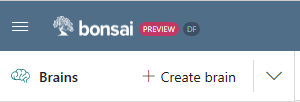

This will prompt for the type of brain to create:

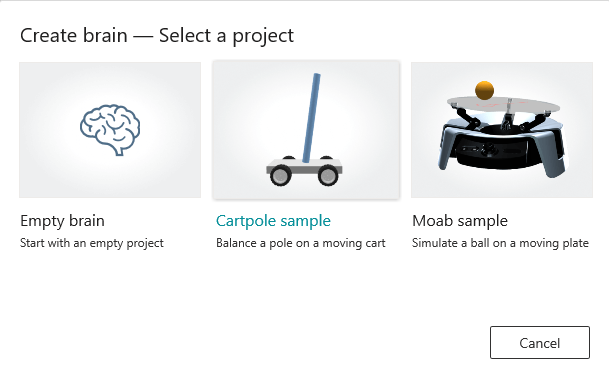

Select `Empty brain `and enter a name in the subsequent prompt:

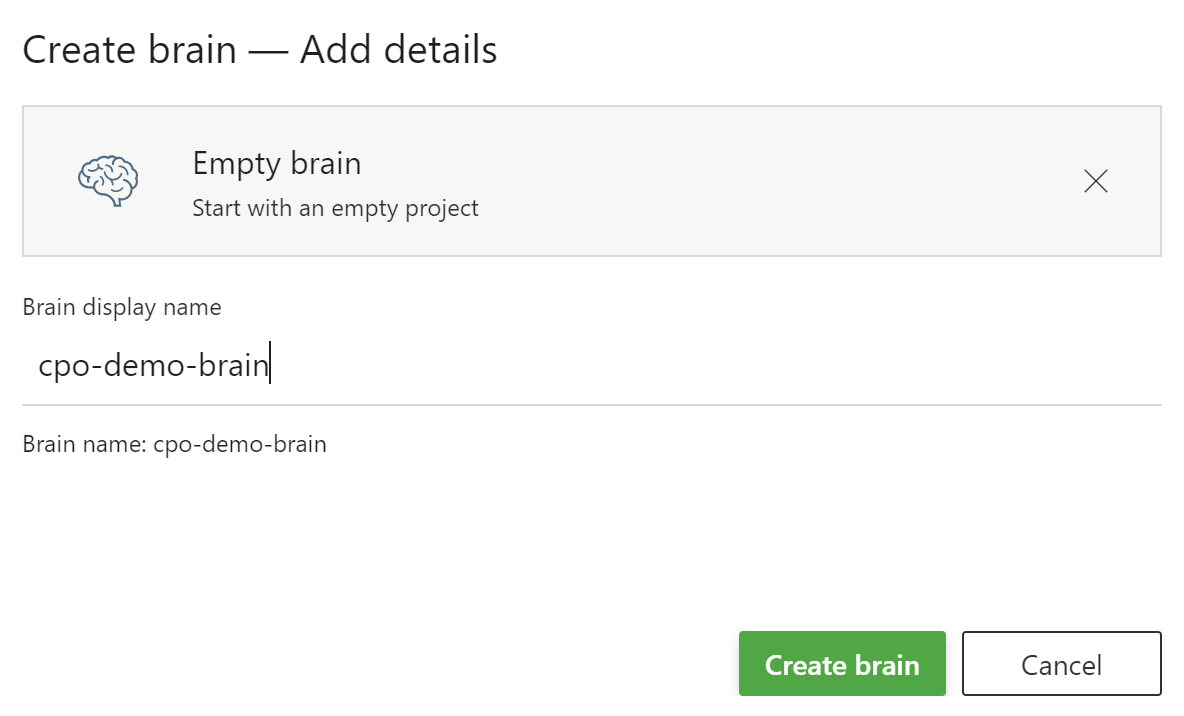

In this example, the brain is called `cpo-demo-brain``. `Click the `Create brain` button`.`

This will create your brain and take you to the **Teach** tab:

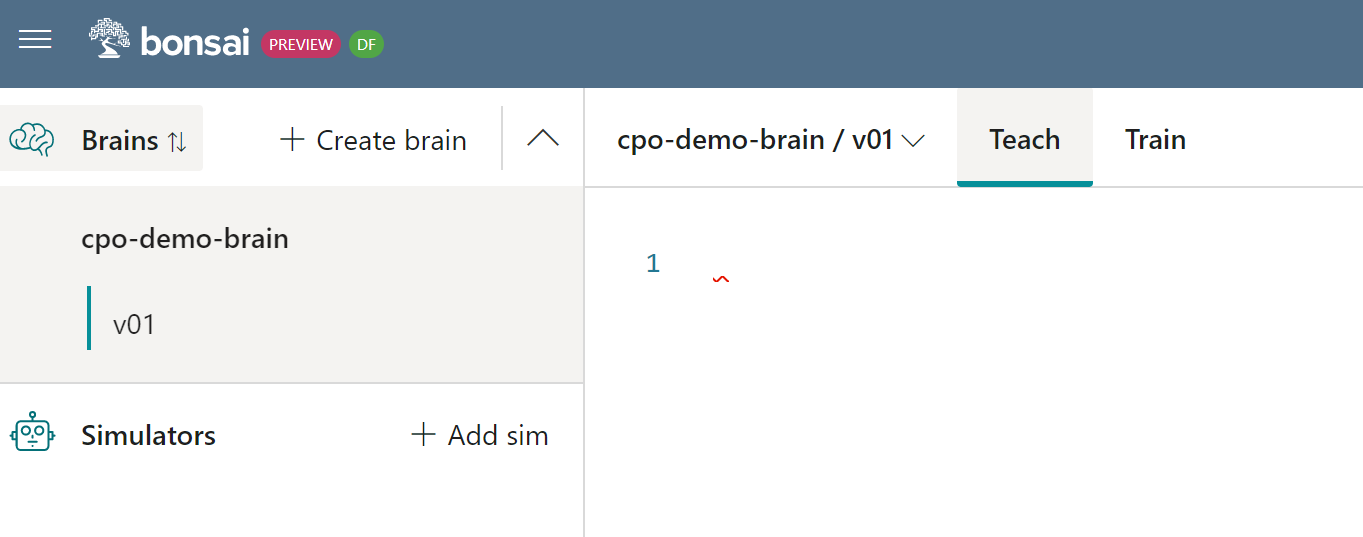

Note, the INK file will be empty in this case (in contrast with Moab or Cartpole samples).

Now, open the "cpo_tutotial_1.ink" file. Copy the full content ("CTRL+a", then "CTRL+c") and paste it on the website so it looks as follows:

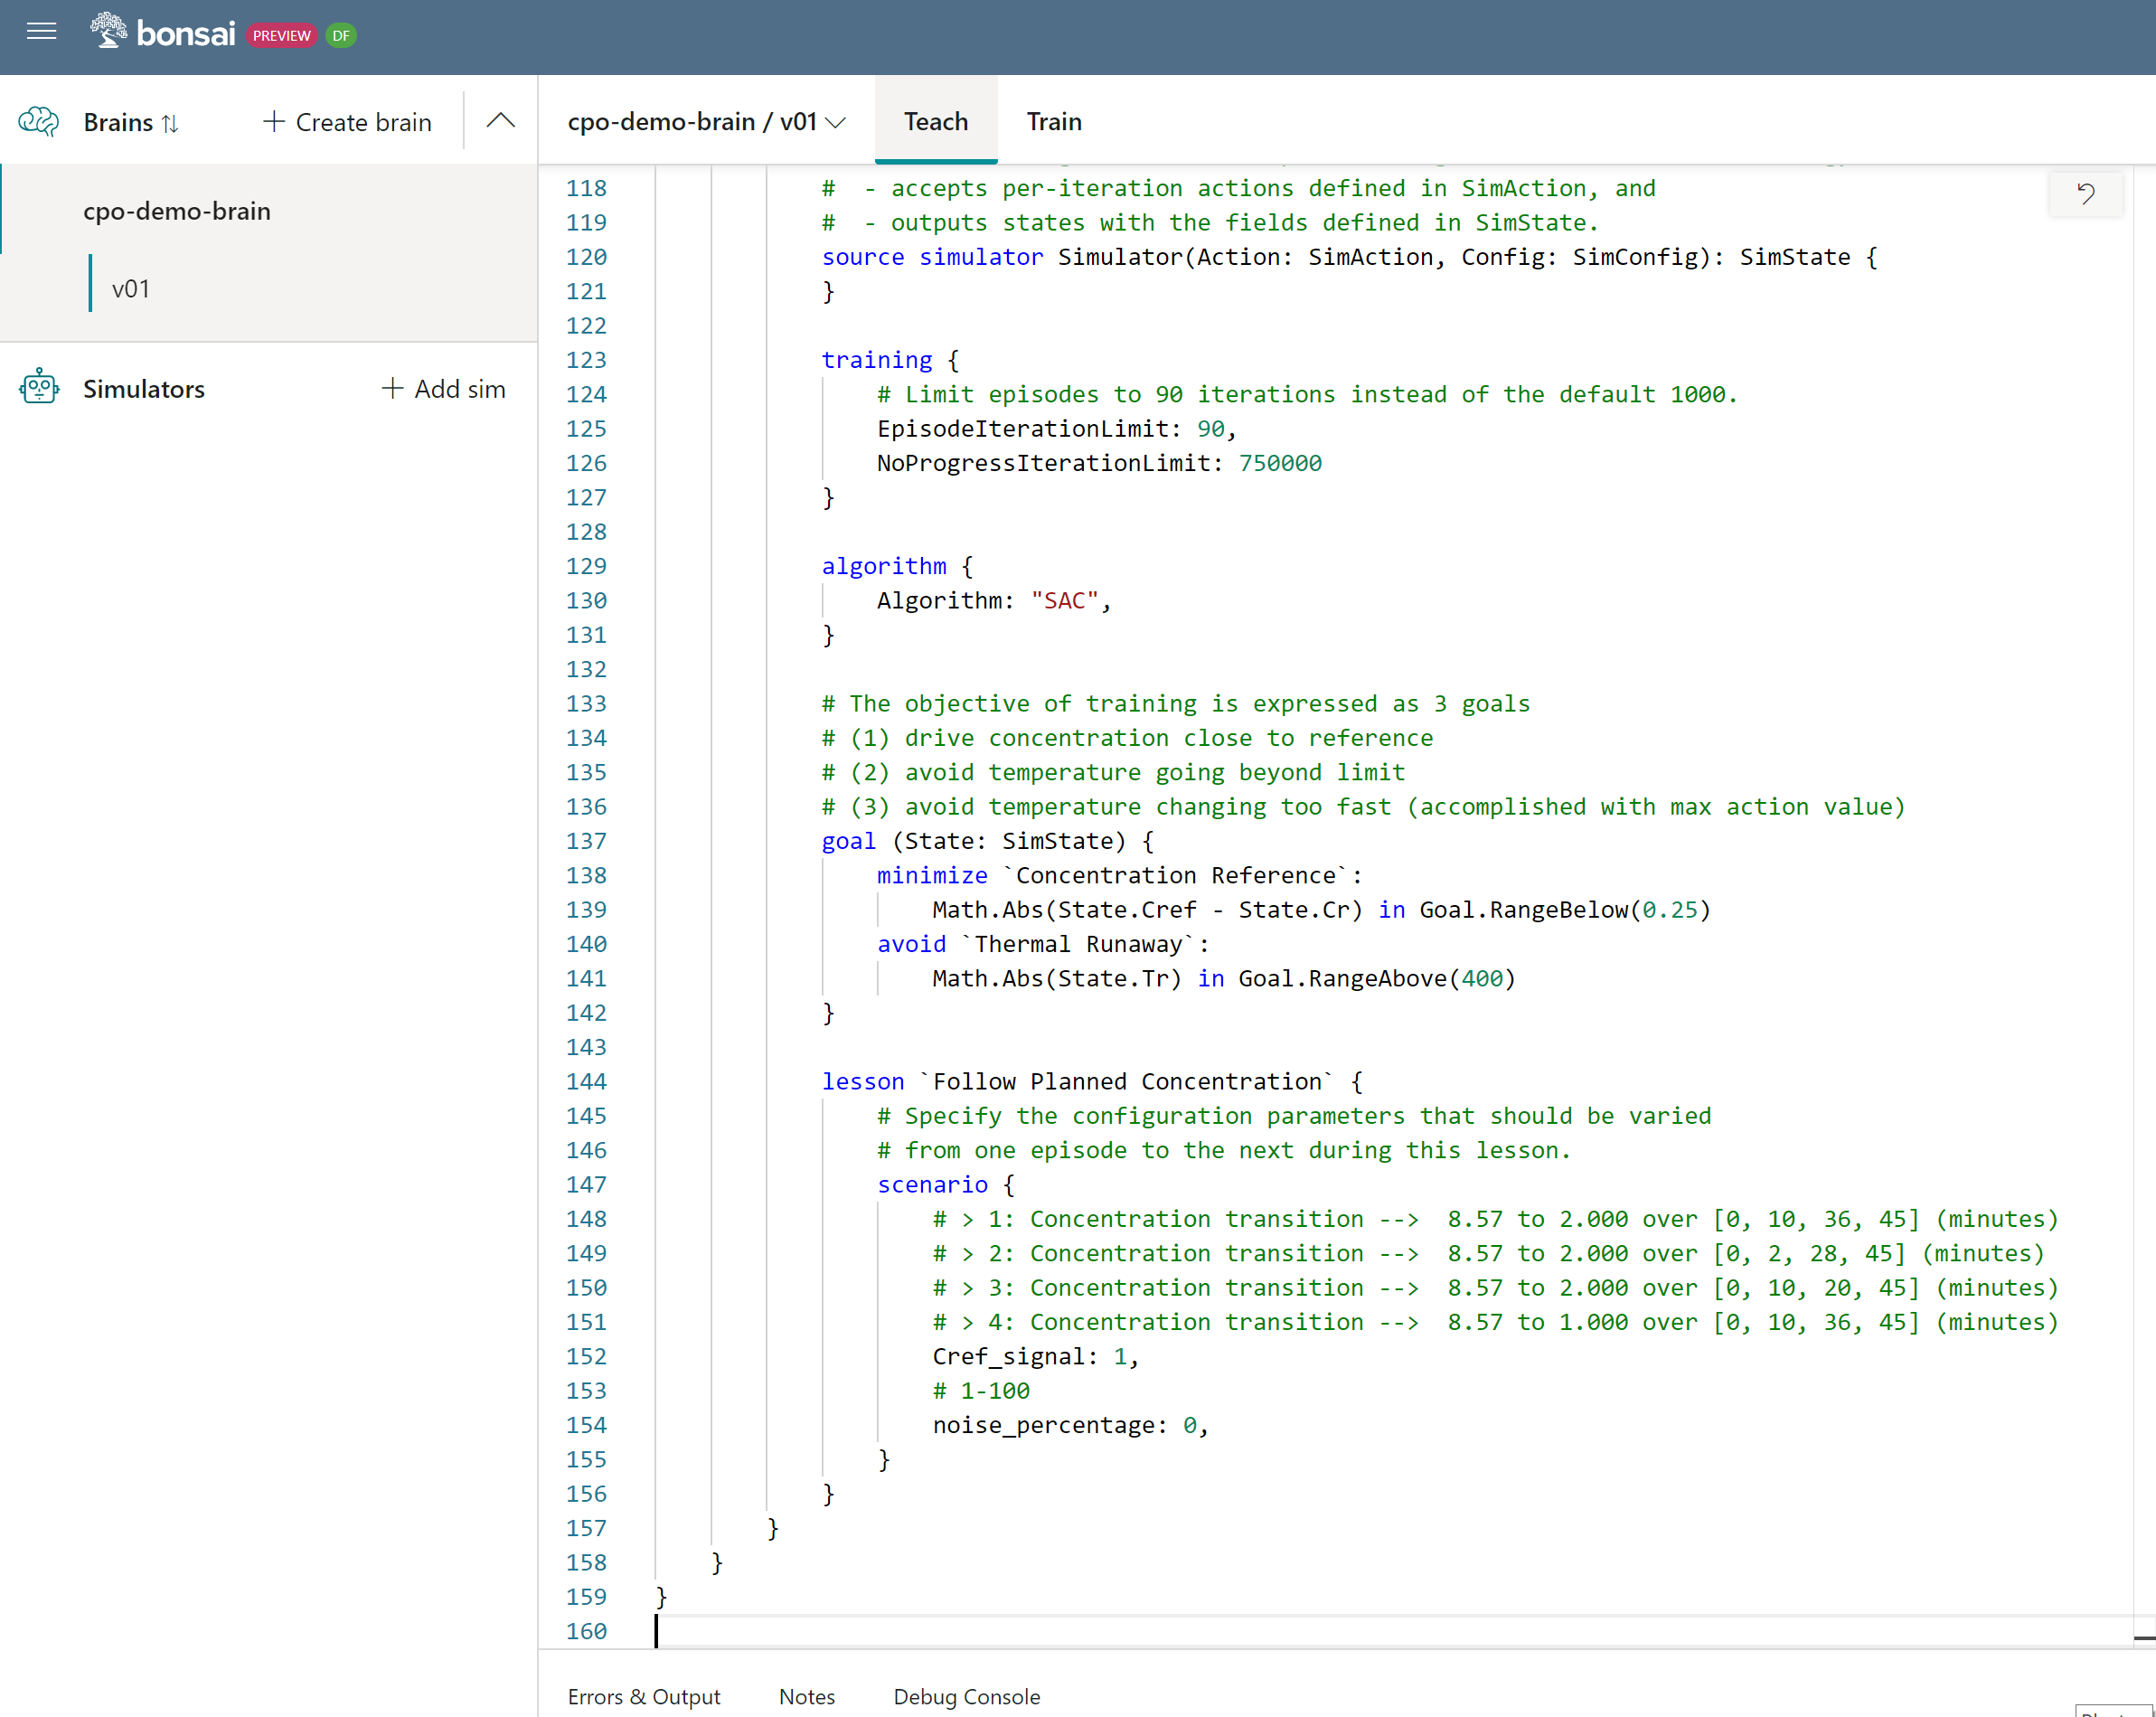

You are now ready to train locally with the Bonsai Controller.

### The `bonsaiConfig `File

The `bonsaiConfig` function is used to setup the connection between your model and the Bonsai platform. Here you describe several key factors:

- **name** - The name of your simulator (you will see this when you connect to Bonsai)

- **url** - Optional. The URL used to connect the Bonsai API service

- **timeout** -- Optional. The value in seconds for a timeout. A default value of 60 seconds is used if this is not explicitly set. **If you receive timeouts when running bonsaiTrain, increase this value up to 300**.

- **workspace** - The workspace value obtained from the Bonsai platform.

- **accessKey** - the access key obtained from the Bonsai platform.

- **outputCSV** - Optional. When running locally, this can be helpful for debugging your model and the Bonsai connection.

- **stateSchema** - *Important. *This is the *order* of the values as they appear in the input parameter of the Bonsai block. Even if you use a Bus as your input the Bonsai block must understand the order of the values. These names must match what is in your inkling code in Bonsai. 

- **actionSchema** - The actions the brain will perform. Input ports to the Moab subsystem. The names must match what is in your inkling code from Bonsai. Order is important. 

- **configSchema** - The values that the Bonsai brain will send during a training episode. These are used as configuration parameters to initialize the model with different states, such as ball size, position, or velocity. 

**Note:** Your model may contain more states than what is in your inkling code for Bonsai. It is OK to have additional states that you send - these are ignored by the platform during execution. However, you must send all states that are required by the inkling code. If you do not, you will receive an error from the platform with an immediate Unregister command.

### Edit `bonsaiConfig`

Now open the `bonsaiConfig` file and replace 

`<your workspace here>` with your Workspace ID 

`<your access key here>` with your Access Key (*not *key ID)

% add workspace id
% add access key

edit bonsaiConfig;


You do not need to change any other values other than `workspace` and `accessKey`.

### Run Bonsai Training with a Single Local Instance 

Now that the connection to Bonsai has been configured, run the `bonsaiTrain` function.

bonsaiTrain; 

Once you see the Sim successfully registered message in the MATLAB Command Window, switch over to the [Bonsai UI](http://preview.bons.ai), click the `Train` button`. `

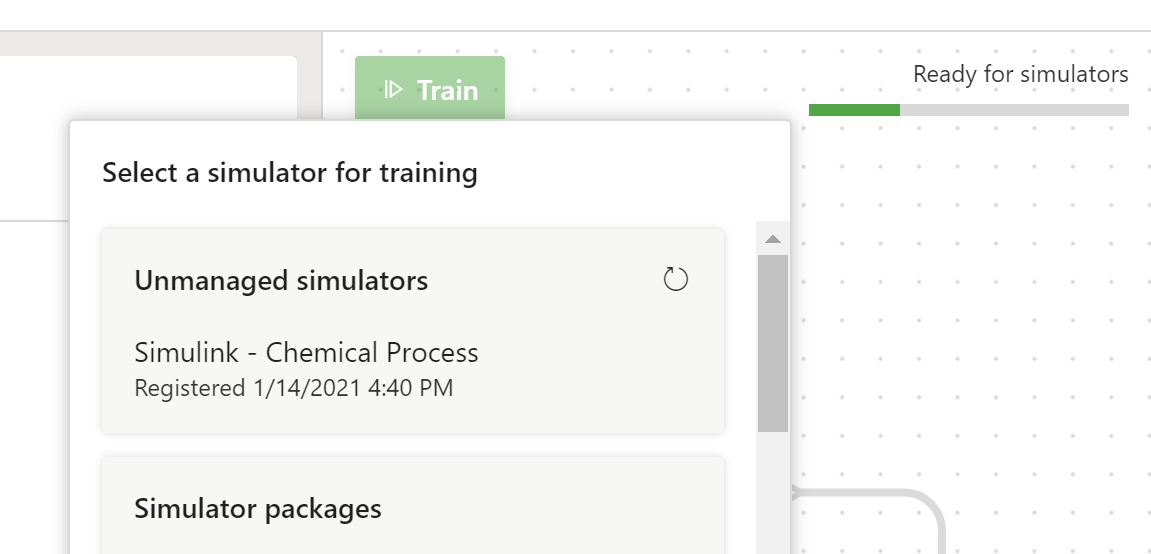

Select `Simulink - Chemical Process` simulator (this assumes you left the .name value the same in bonsaiConfig). 

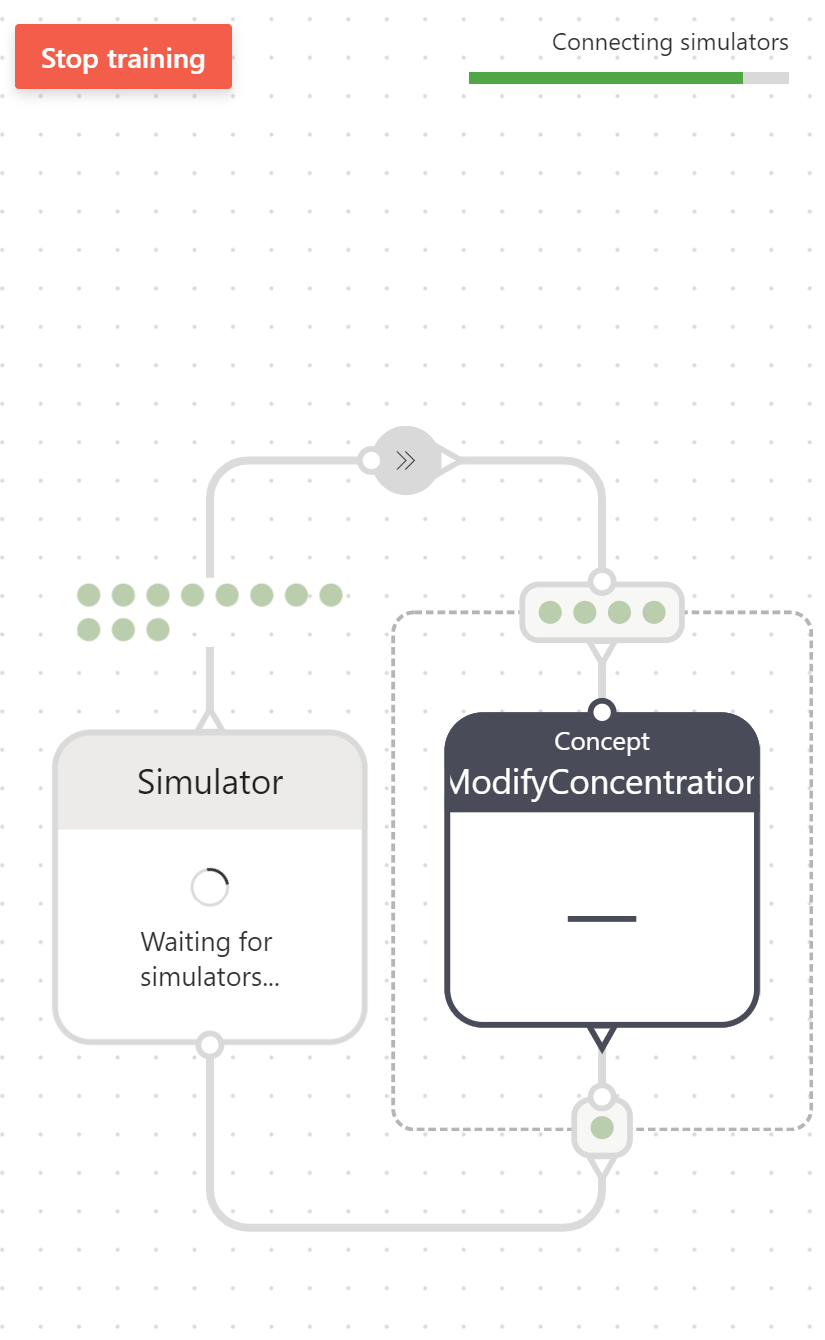

After a short time (typically <2 minutes) the sim will connect:

[TODO] Include image after a short time with simulator connected

At this point the model is launched and parameters are set, so you may see a delay while this occurs and Mechanics Explorer launches.

After this process completes you will see the iterations per second displayed: 

[TODO] Include image after a short time with simulator connected. Now, with ITERATIONS SHOWN

Check the MATLAB Command Window to see a series of outputs indicating communication with the Bonsai brain.

Connection speeds vary, but most models operate at about 2-3 iterations per second. 

To stop training, click `Stop Training `in the Bonsai UI.

**Note:** To terminate the simulation in MATLAB, use Ctrl+C in the Command Window. Be sure to disable Fast Restart from the Simulation tab in the Simulink model.

## Zip, Upload and Scale Your Model

Scaling the model greatly improves training times. Once you have verified your model connects locally, you can close Simulink and zip the entire contents of the folder that contains the model. 

For example, if your folder structure is:

`chemical-process-optimization `

`└─── img`

`|    └── ... image files ... `

`|─── bonsaiAssess.m`

`|─── bonsaiConfig.m`

`|─── bonsaiTrain.m`

`|─── Chemical_Process_Optimization.mlx`

`|─── ChemicalProcessOptimization.slx`

`|─── cpo_tutorial_1.ink`

`|─── CSTRData.mat`

`|─── init_vars.m`

`|─── LICENSE`

`|─── README.md`

`└─── run_benchmark.m`

Then you only need to zip the parent **chemical-process-optimization** folder. It is suggested you remove your` slprj` folder and` .slxc `files before zipping up the folder contents. You also do not need any` .csv `files, neither the 'img' folder`. `Call the file `chemical-process-optimization.zip. `

### Upload the Model

Back in the Bonsai UI, next to `Simulators``,` click the `Add sim` button.

This will open a dialog:

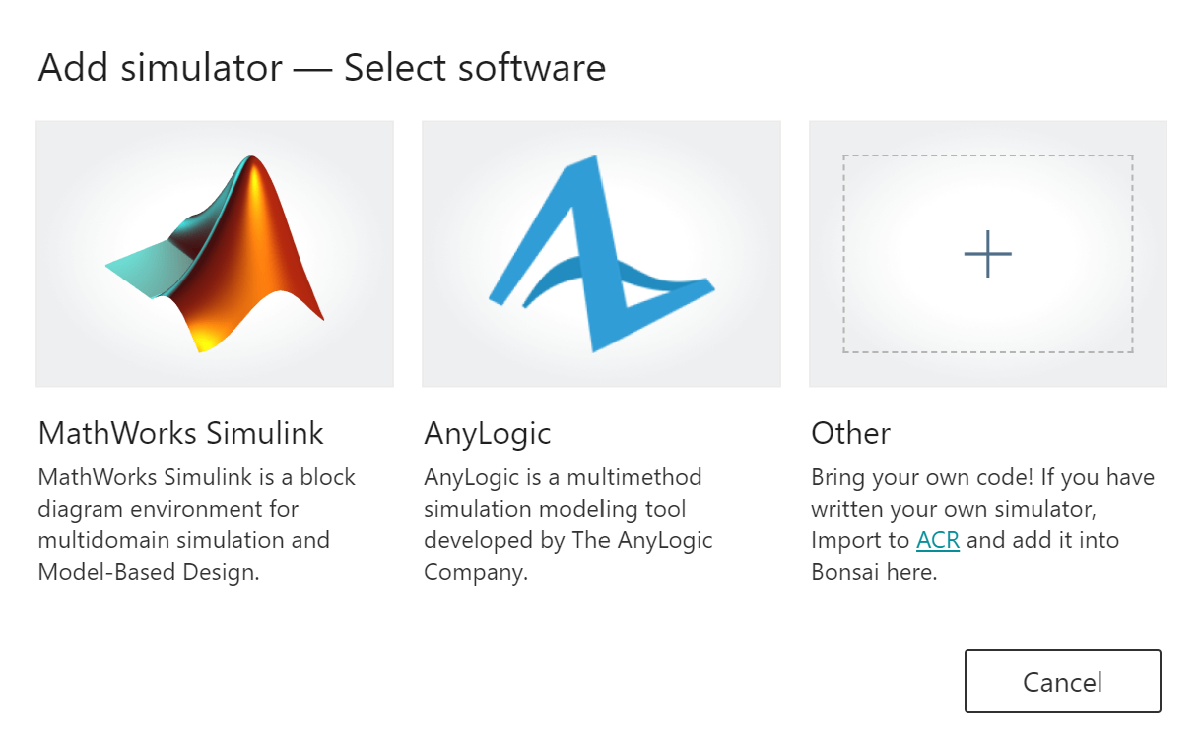

Select `MathWorks``. `Then you can upload your zip file`:`

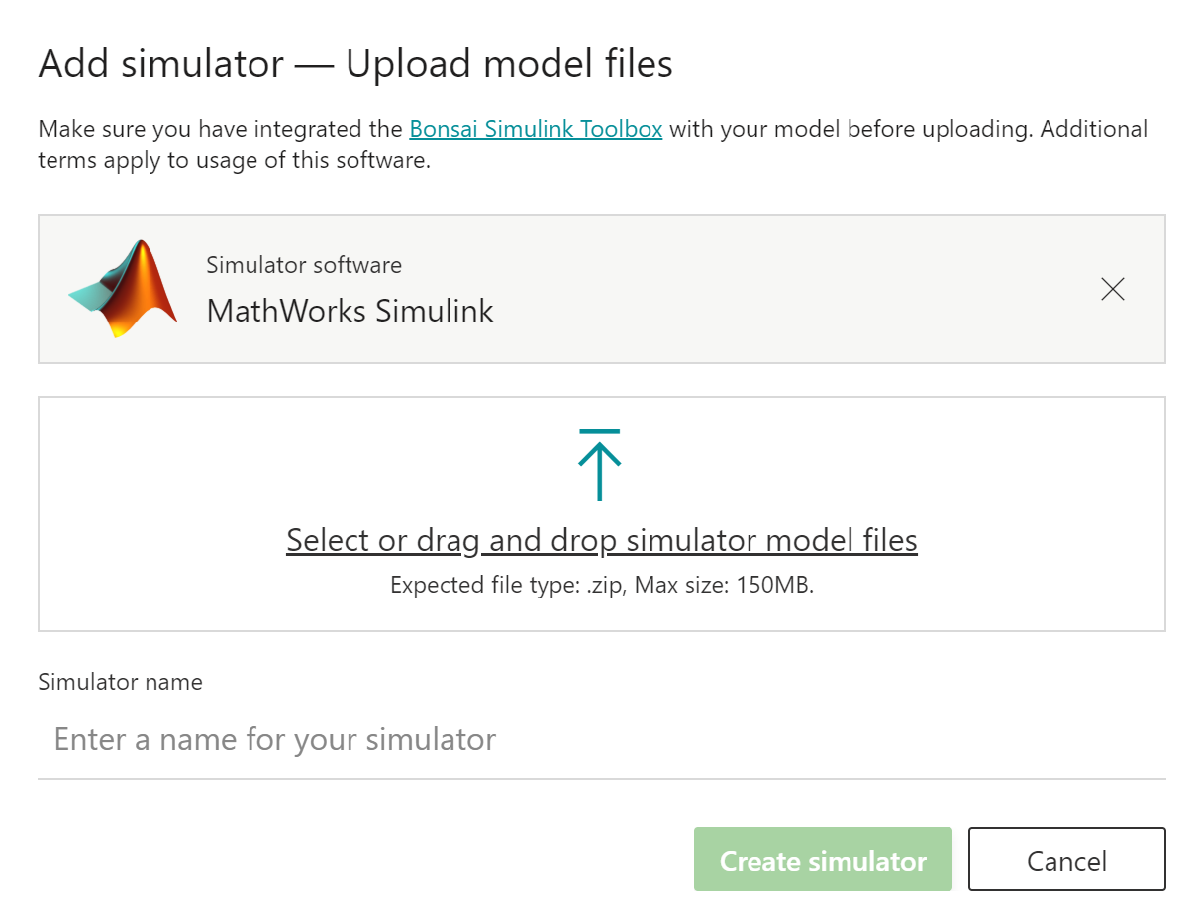

Select or drag the `chemical-process-optimization.zip `file created previously`. `

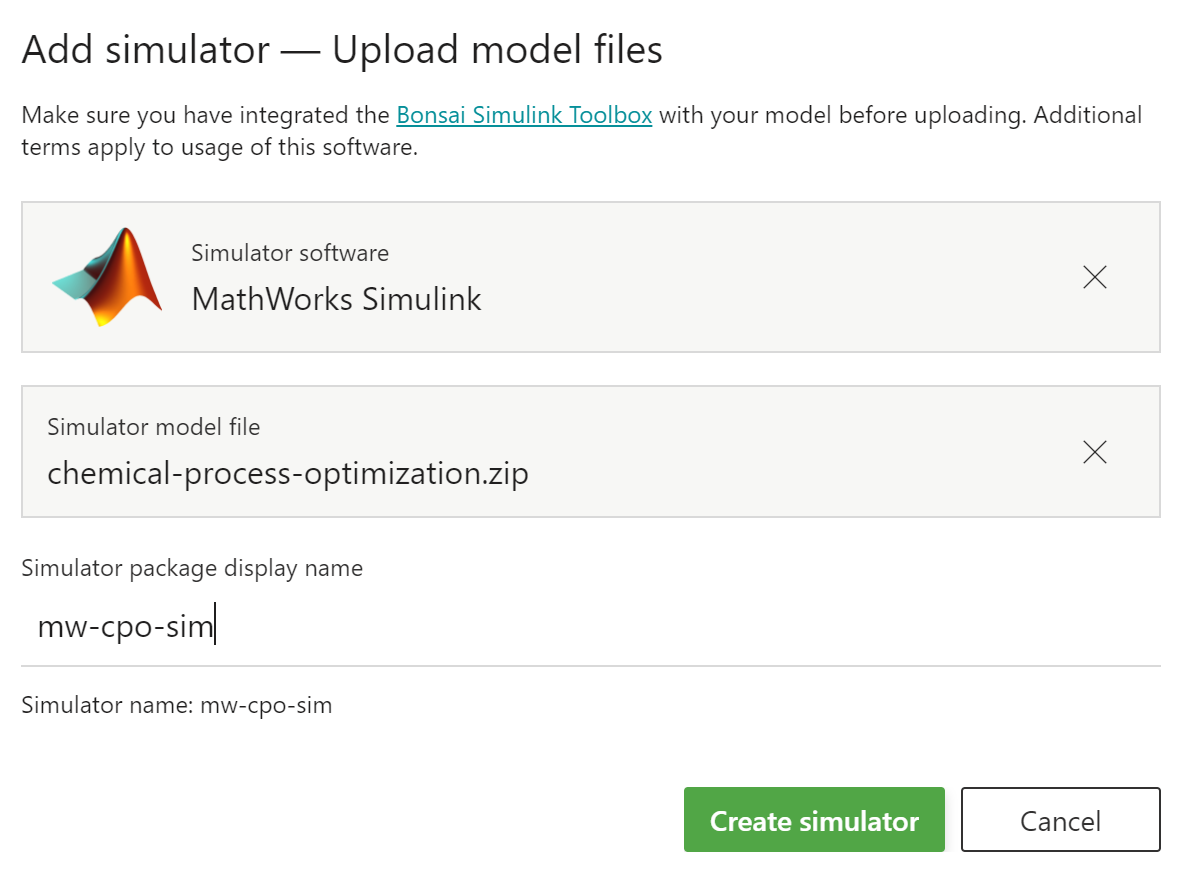

Give your simulator a name, then click `Create simulator``. `

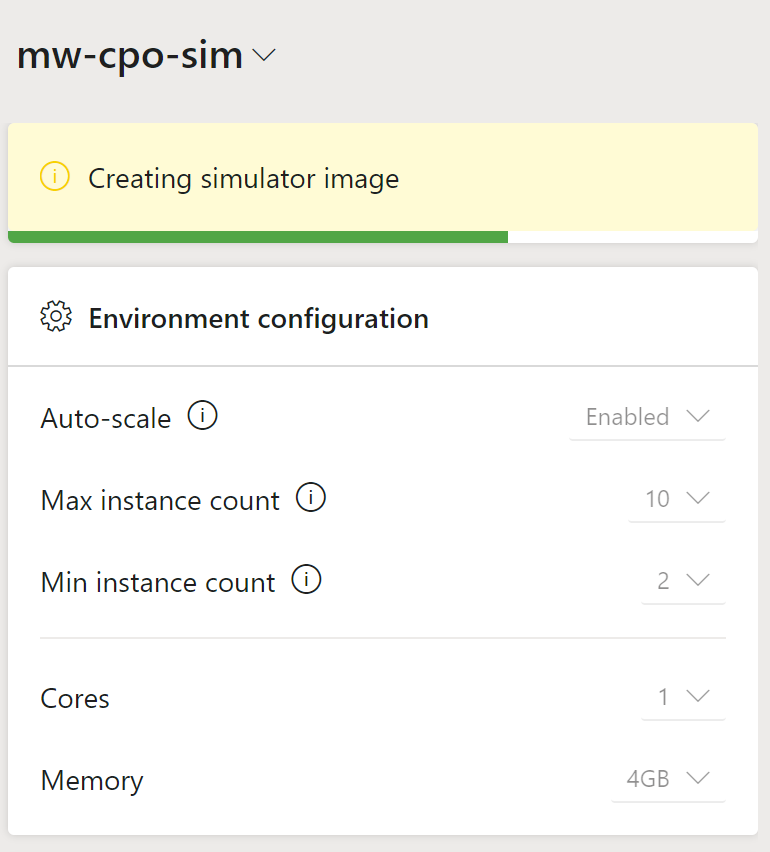

**Note: ***It may take up to 20 minutes to create the simulator image. *You will the ACR path displayed after successful creation:

[TODO] Include image of the ACR path once created (hiding personal workspace directory)

After the simulator is created you will see the new simulator appear under the `Simulators`` section.`

**Note: **Be sure your brain is not training prior to changing the package statement.

Now click the `Teach` tab. 

In the simulator definition in inkling ("teach" tab on https://preview.bons.ai), you will need to include the name of the simulator you gave during the Add Simulator dialog above.

### Scale Your Training

Now click the `Train` button for your brain. This will create several instances (from 1-50) using your uploaded model to train your brain.

**Note: **It may take up to 10 minutes for your simulators to connect.

## Tutorials

[TODO] Shall we remove this section?

## Assessing Brain Performance

Assessment allows you to test the performance of a trained brain while still hosting that brain in the Bonsai platform. 

After training your brain(s) you will want to assess their performance. Make sure your Bonsai Controller is enabled in Simulink. Run:

bonsaiAssess;

This will begin assessment and connect to the Bonsai platform, similar to training. If your model is not open this will also open the model.

Click the `Run` button in Simulink.

In the Bonsai UI, click the `Start Assessment `button.

Click the `Simulink - Chemical Process` simulator. 

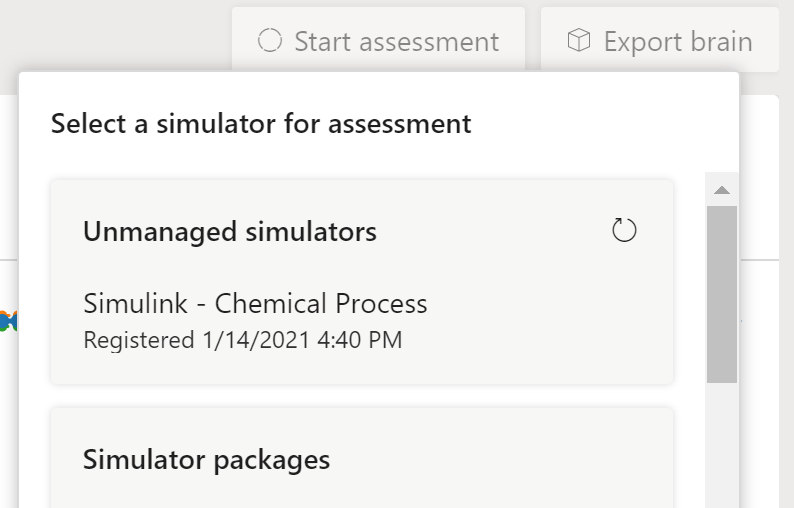

Your local model will iterate using the brain in assessment mode.

If you receive the message `Last event was Unregister, done requesting events `then you may need to increase the timeout value in bonsaiConfig.